clc
clear

**1.7**

sig1 = 1*randn(1, 1000);
sig2 = 0.2 + 1*randn(1000,1);


 randn - 正态分布的随机数
    此 MATLAB 函数 返回一个从标准正态分布中得到的随机标量。

    X = randn
    X = randn(n)
    X = randn(sz1,...,szN)
    X = randn(sz)

    X = randn(___,typename)
    X = randn(___,'like',p)

    X = randn(s,___)

    另请参阅 <a href="F:\matlab\help\matlab\ref\randi.html">randi</a>, <a href="F:\matlab\help\matlab\ref\rand.html">rand</a>, <a href="F:\matlab\help\matlab\ref\rng.html">rng</a>, <a href="F:\matlab\help\matlab\ref\randstream.html">RandStream</a>, <a href="F:\matlab\help\matlab\ref\sprand.html">sprand</a>, <a href="F:\matlab\help\matlab\ref\sprandn.html">sprandn</a>, <a href="F:\matlab\help\matlab\ref\randperm.html">randperm</a>

    randn 的文档
    名为 randn 的其他函数



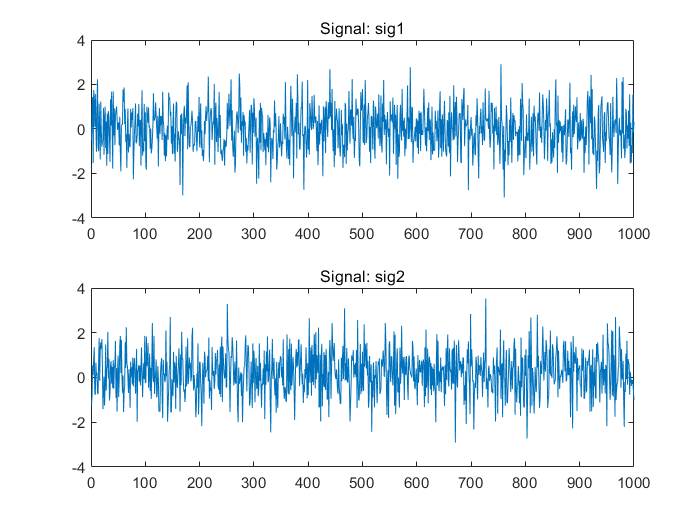


figure;
subplot(2, 1, 1);
plot(sig1);
title('Signal: sig1');

subplot(2, 1, 2);
plot(sig2);
title('Signal: sig2');

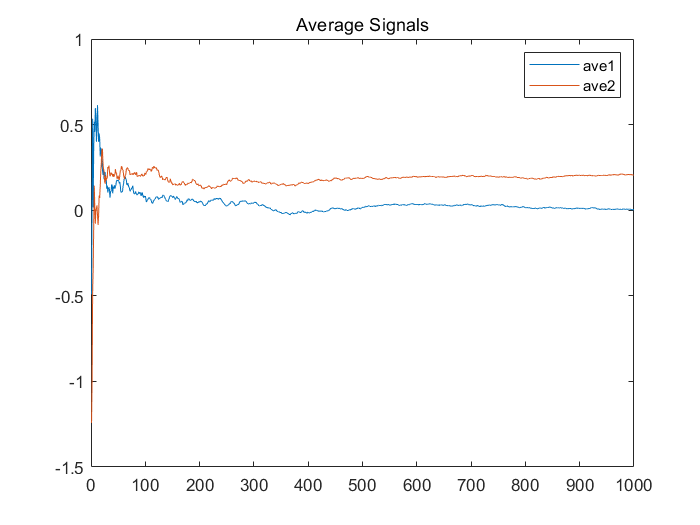



ave1 = zeros(1, 1000);
ave2 =zeros(1, 1000);
for n = 1:1000
    ave1(n) = mean(sig1(1:n));
    ave2(n) = mean(sig2(1:n));
end
figure;
plot(ave1);
hold on;
plot(ave2);
title('Average Signals');
legend('ave1', 'ave2');